# noise

clear;
Fs = 44100;
T = 1 / Fs;
L = Fs * 1;
% X = zeros(L, 1);
t = (0:L-1)*T;
% size(X)
% mags = zeros(1, L/2+1) + 1;
% mags = randn(1, L/2+1);
mags = linspace(0, 1, L/2 + 1);

% mags = mags - 1/22050 * 440*4;
% mags = exp(-200*mags.*mags);

mags = exp(-2*mags) .* sin(22*mags).^222;

% mags = exp(-200*mags);
% mags(1:end) = 1;
mags = mags - min(mags)

mags =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


% mags(2000:end) = 187;
% phases = zeros(1, L/2+1);
% phases = randn(1, L/2+1);
% phases = rand(1, L/2+1);
% phases = mod(randn(1, L/2+1), 1);
phases = linspace(pi, -pi, L/2 + 1);
phases = 0*phases + 1*rand(1, L/2+1) + 0.0*sin(phases*2000000/pi + 0.5);
% phases = tan(phases*20200);
phases = phases - min(phases);
phases = phases / max(phases);
phases = (phases - 0.5) * 2;
phases = phases * pi;

f = Fs/L*(0:(L/2));
plot(f(1:end/10),mags(1:end/10)) 

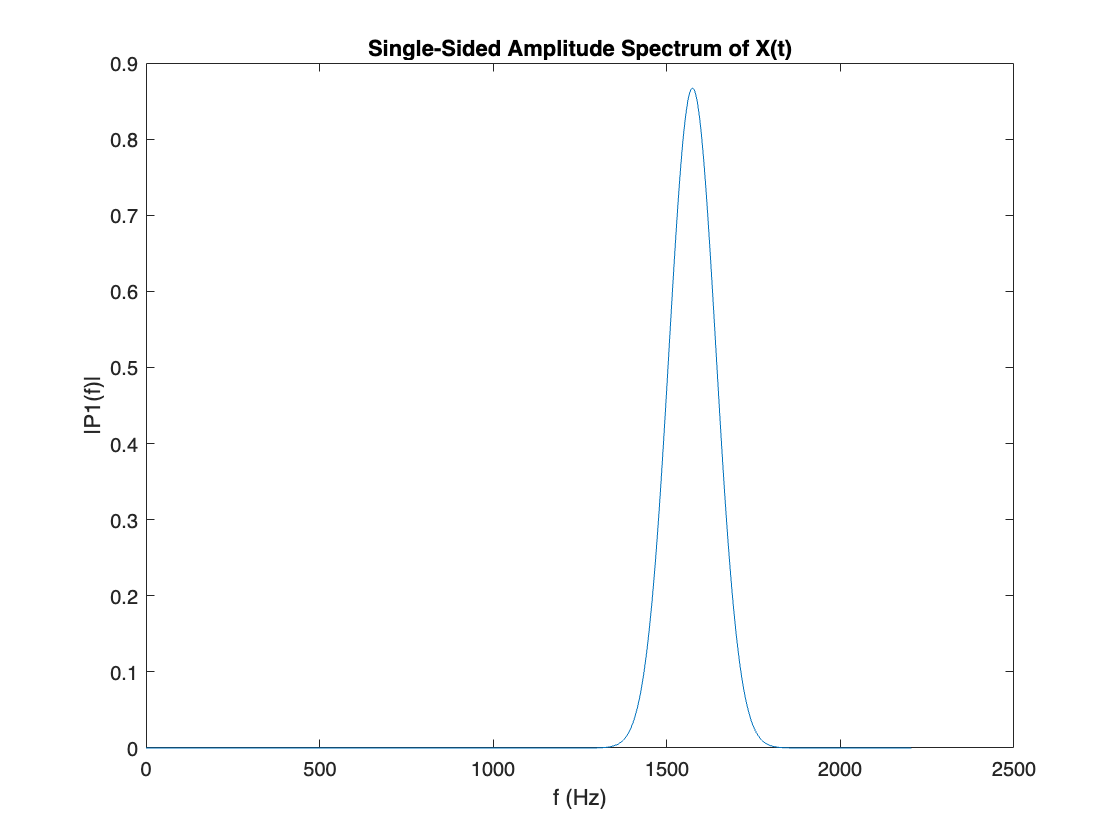

title("Single-Sided Amplitude Spectrum of X(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

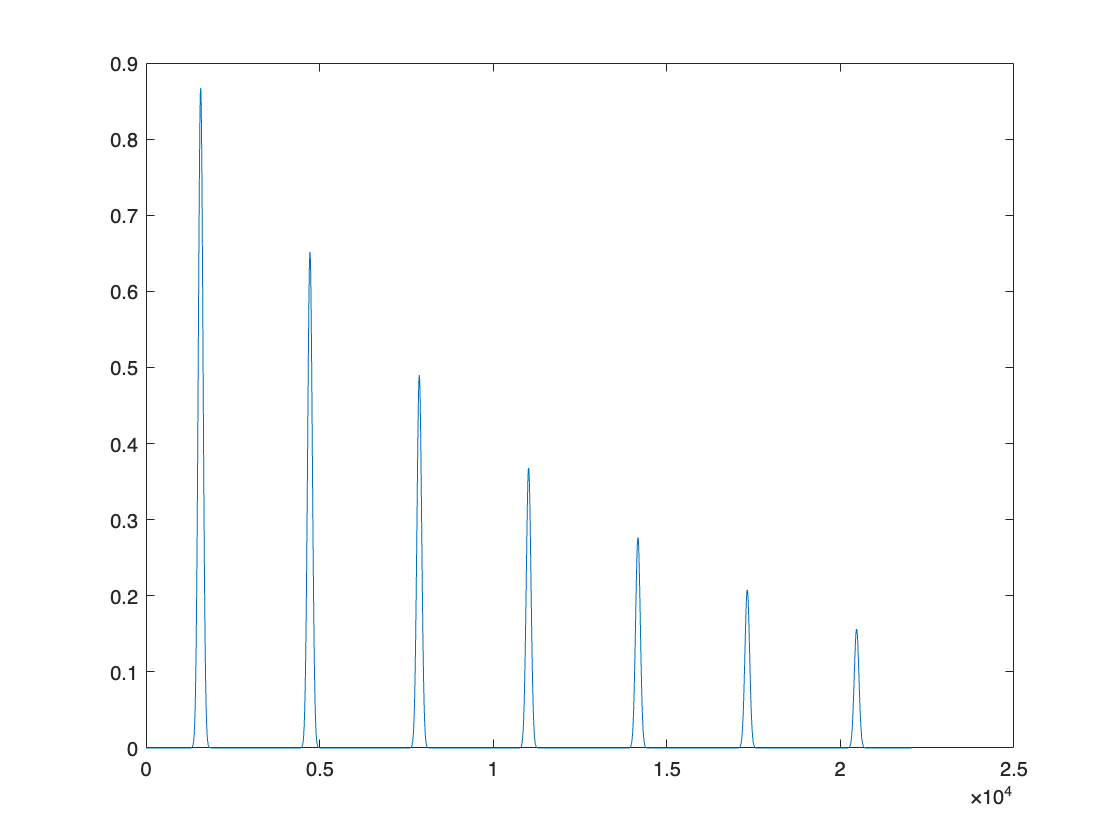

plot(f,mags)

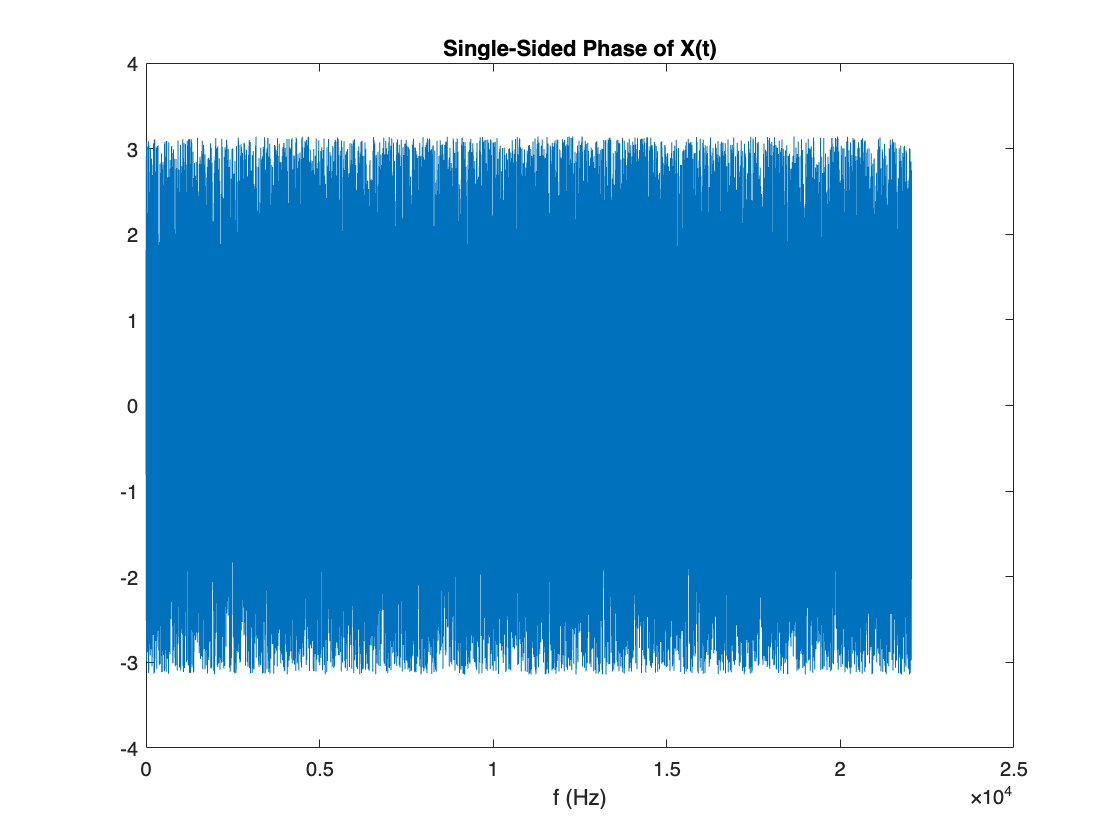


f = Fs/L*(0:(L/2));
plot(f,phases) 
title("Single-Sided Phase of X(t)")
xlabel("f (Hz)")

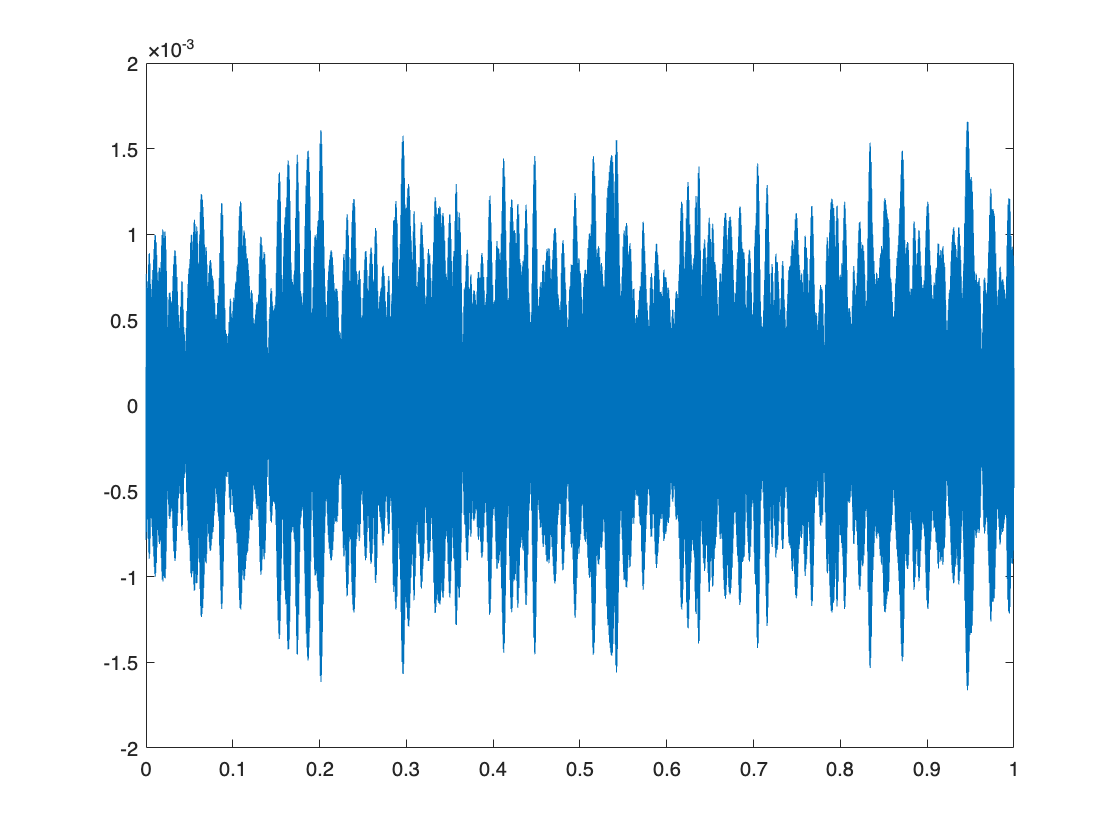


recs = zeros(1, L);
for i = 0:(L/2)
    mag = mags(i+1);
    phase = phases(i+1);
    add = 2*mag/L * cos(2*pi*t*Fs/L*i + 1*phase);
    if i == 0 || i == L/2
        add = add / 2;
    end
    recs = recs + add;
end
plot(t,recs);

recs(1)

ans = -7.8455e-04

recs(end)

ans = -4.8274e-04

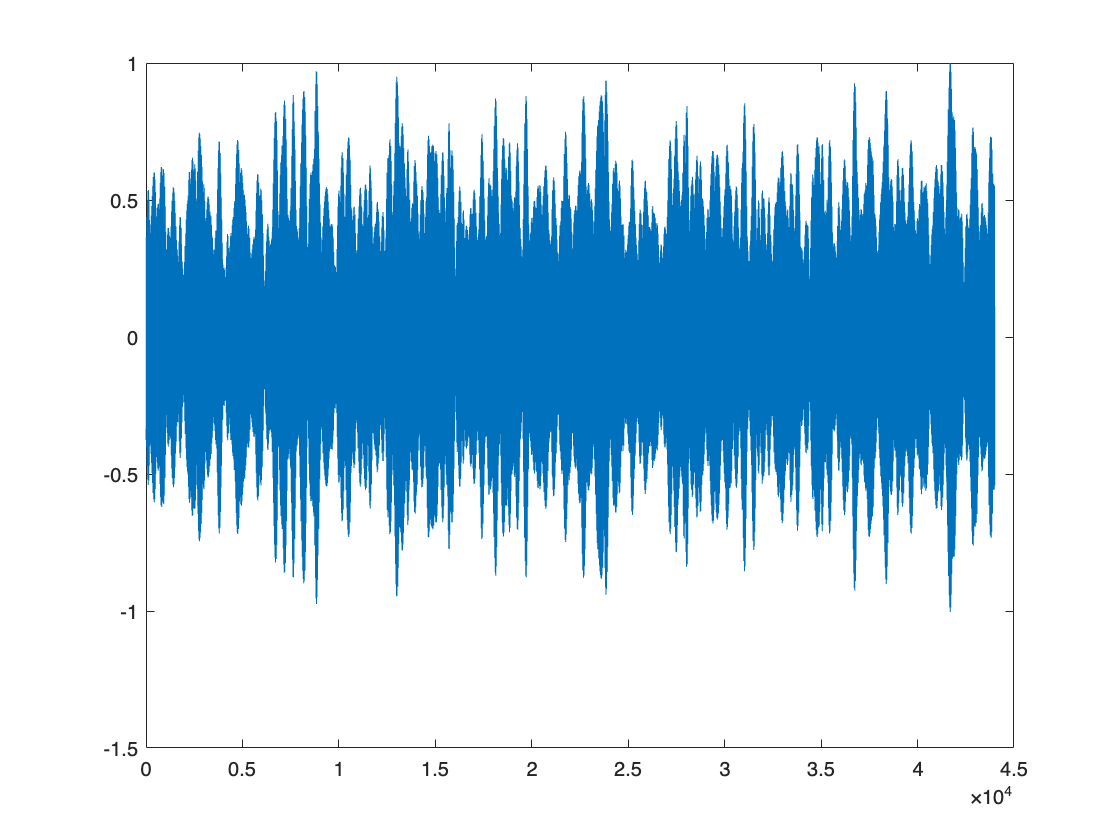

smoothening = 50;

recs = recs(1+smoothening:end-smoothening);
recs = recs / max(recs);
plot((1:L - 2*smoothening),recs);


prepend = linspace(0, recs(1), smoothening)

prepend =          0   -0.0068   -0.0137   -0.0205   -0.0274   -0.0342   -0.0411   -0.0479   -0.0548   -0.0616   -0.0685   -0.0753   -0.0822   -0.0890   -0.0958   -0.1027   -0.1095   -0.1164   -0.1232   -0.1301   -0.1369   -0.1438   -0.1506   -0.1575   -0.1643   -0.1711   -0.1780   -0.1848   -0.1917   -0.1985   -0.2054   -0.2122   -0.2191   -0.2259   -0.2328   -0.2396   -0.2465   -0.2533   -0.2601   -0.2670   -0.2738   -0.2807   -0.2875   -0.2944   -0.3012   -0.3081   -0.3149   -0.3218   -0.3286   -0.3354


append = linspace(recs(end), 0, smoothening)

append =     0.1148    0.1124    0.1101    0.1078    0.1054    0.1031    0.1007    0.0984    0.0960    0.0937    0.0914    0.0890    0.0867    0.0843    0.0820    0.0796    0.0773    0.0750    0.0726    0.0703    0.0679    0.0656    0.0632    0.0609    0.0586    0.0562    0.0539    0.0515    0.0492    0.0468    0.0445    0.0422    0.0398    0.0375    0.0351    0.0328    0.0305    0.0281    0.0258    0.0234    0.0211    0.0187    0.0164    0.0141    0.0117    0.0094    0.0070    0.0047    0.0023         0


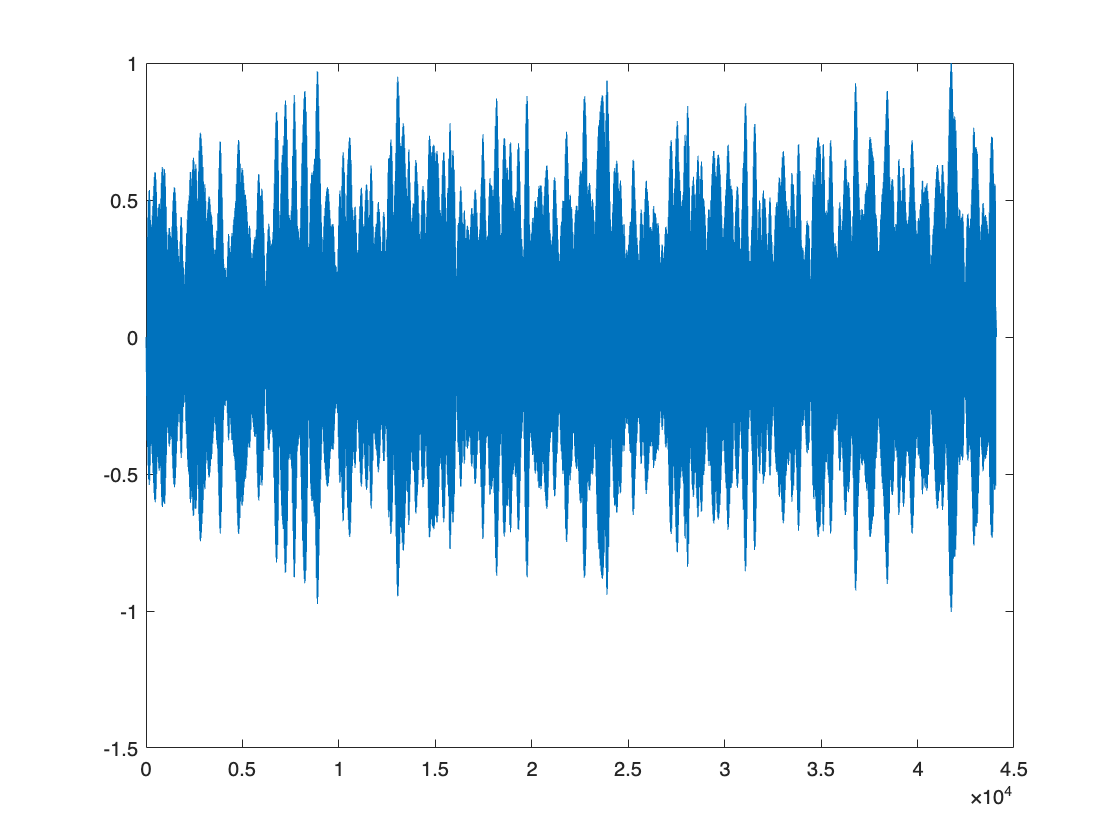

recs = [prepend recs append];
plot((1:L),recs);

recs(1)

ans = 0

recs(end)

ans = 0

min(recs)

ans = -1.0036

max(recs)

ans = 1

audiowrite("recr.wav",recs,Fs)